load(OptResults3)

Tau = 0.06; % initial value of time constants, based on Franken et al. 1992
scalePWP = -0.0108; % set PWP to have no effect
circadianAmp = 0.0229; % set circadian process to have no effect
circadianPhase = -1.4823; % set circadian process to have no phase
sizePWP = [0,0.1,5]; % Possible Values. [X,Y,Z] translated to X:Y:Z
shiftPWP = [-5,0.1,5];  % Possible Values. [X,Y,Z] translated to X:Y:Z

c=parcluster

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-mbp
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

j5=batch(@example2_Optimization,0,{rawData_all, 1, OptResults_all})

j5 = 

 Job

    Properties: 

                   ID: 51
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 21-Sep-2022 12:12:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

load(OptResults_all)

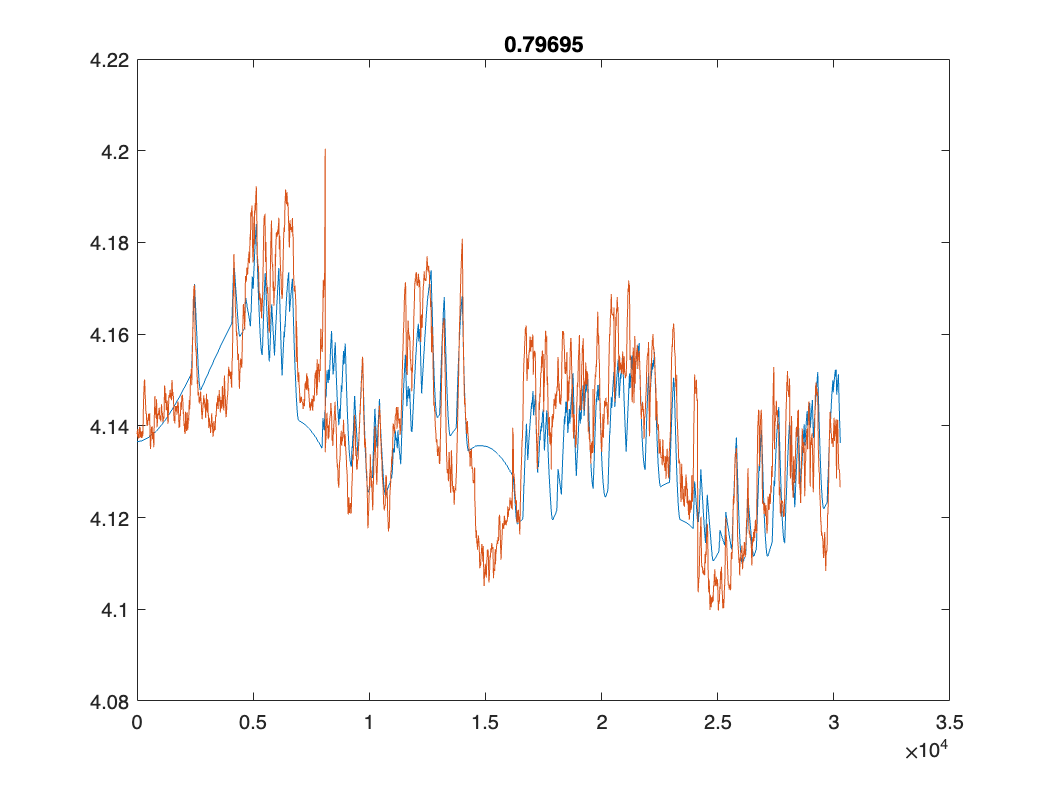

figure
plot(simulatedT)
hold on
plot(rawT)
title(num2str(correlation))